# Elevated Plus Maze (EPM) Analysis

**FINAL – TrAQ Compatible, Fixed Arm Orientation**

CLOSED arms: TOP & BOTTOM (vertical)

OPEN arms  : LEFT & RIGHT (horizontal)

 BODY  -> time & speed

 NOSE  -> entries (TrAQ definition)

 Anxiety indices: OAT%, OAE%

**A.Babaei**

clearvars -except track;
clc;

%% ================= USER PARAMETERS =================
pos_smooth_win    = 5;        % frames
speed_smooth_win  = 5;        % frames
debounce_time_s   = 0.30;     % seconds
px_to_cm          = 0.1;      % <<< SET YOUR CALIBRATION

%% ================= LOAD TRACK ======================
if ~exist('track','var')
    load('Out_Stim2');
end

%% ================= TIME BASE =======================
if isfield(track,'Time') && numel(track.Time)>1
    t  = track.Time(:);
    dt = mean(diff(t));
else
    fps = getfield(track,'FrameRate',30);
    dt  = 1/fps;
    t   = (0:size(track.Centroid,1)-1)'*dt;
end

nFrames      = numel(t);
total_time_s = (nFrames-1)*dt;

%% ================= POSITION (ROBUST) ==============
% BODY
if isfield(track,'Body_Centroid')
    Body = double(track.Body_Centroid);
elseif isfield(track,'Centroid')
    Body = double(track.Centroid);
else
    error('No BODY position field found');
end

% NOSE
if isfield(track,'Nose')
    Nose = double(track.Nose);
elseif isfield(track,'Head')
    Nose = double(track.Head);
else
    error('No NOSE/HEAD position field found');
end

if size(Body,1)==2, Body = Body'; end
if size(Nose,1)==2, Nose = Nose'; end

Body(:,1) = smoothdata(Body(:,1),'movmean',pos_smooth_win);
Body(:,2) = smoothdata(Body(:,2),'movmean',pos_smooth_win);
Nose(:,1) = smoothdata(Nose(:,1),'movmean',pos_smooth_win);
Nose(:,2) = smoothdata(Nose(:,2),'movmean',pos_smooth_win);

Xb = Body(:,1); Yb = Body(:,2);
Xn = Nose(:,1); Yn = Nose(:,2);

%% ================= SPEED ==========================
dx = [0; diff(Xb)];
dy = [0; diff(Yb)];
speed_px = sqrt(dx.^2 + dy.^2);
speed_px = smoothdata(speed_px,'movmean',speed_smooth_win);
speed_cm_s = speed_px * px_to_cm / dt;

%% ================= ZONE GEOMETRY ==================
% Explicit EPM geometry (FIXED)
cx = median(Xb);
cy = median(Yb);

center_rx = prctile(abs(Xb-cx),15);
center_ry = prctile(abs(Yb-cy),15);

arm_width_x = prctile(abs(Xb-cx),30);
arm_width_y = prctile(abs(Yb-cy),30);

%% ================= BODY ZONES (TIME) ===============
% 1 = Center | 2 = Open (horizontal) | 3 = Closed (vertical)
zone_body = zeros(nFrames,1);

for i = 1:nFrames
    dx = abs(Xb(i)-cx);
    dy = abs(Yb(i)-cy);

    if dx<=center_rx && dy<=center_ry
        zone_body(i)=1;               % Center
    elseif dy>center_ry && dx<=arm_width_x
        zone_body(i)=3;               % Closed (TOP/BOTTOM)
    else
        zone_body(i)=2;               % Open (LEFT/RIGHT)
    end
end

%% ================= NOSE ZONES =====================
zone_nose = zeros(nFrames,1);

for i = 1:nFrames
    dx = abs(Xn(i)-cx);
    dy = abs(Yn(i)-cy);

    if dx<=center_rx && dy<=center_ry
        zone_nose(i)=1;
    elseif dy>center_ry && dx<=arm_width_x
        zone_nose(i)=3;
    else
        zone_nose(i)=2;
    end
end

%% ================= NOSE DEBOUNCING =================
min_frames = round(debounce_time_s/dt);

zone_nose_db = zone_nose;
for z=1:3
    mask = zone_nose==z;
    mask = movmedian(double(mask),min_frames)>0.5;
    zone_nose_db(mask)=z;
end
zone_nose = zone_nose_db;

%% ================= TIME METRICS ===================
%% ===== CORRECT ARM-TIME MAPPING (FIXED) =====
% In THIS experiment:
%   Vertical arms   = CLOSED
%   Horizontal arms = OPEN

% zone_body:
%   1 = Center
%   2 = Horizontal arms
%   3 = Vertical arms

is_center = (zone_body == 1);

% FIXED mapping
is_open   = (zone_body == 3);   % VERTICAL arms = OPEN
is_closed = (zone_body == 2);   % HORIZONTAL arms = CLOSED

time_center_s = sum(is_center) * dt;
time_open_s   = sum(is_open)   * dt;
time_closed_s = sum(is_closed) * dt;

fprintf('Time check: %.6f s\n', ...
    time_center_s + time_open_s + time_closed_s - total_time_s);

Time check: 0.033367 s



%% ================= ENTRY METRICS ==================
prevN = zone_nose(1:end-1);
currN = zone_nose(2:end);

entries_open   = sum(prevN==1 & currN==2);   % Center→Open
entries_closed = sum(prevN==1 & currN==3);   % Center→Closed
entries_center = sum(prevN~=1 & currN==1);

%% ================= SPEED METRICS ==================
mean_speed_overall = mean(speed_cm_s,'omitnan');
mean_speed_center  = mean(speed_cm_s(zone_body==1),'omitnan');
mean_speed_open    = mean(speed_cm_s(zone_body==2),'omitnan');
mean_speed_closed  = mean(speed_cm_s(zone_body==3),'omitnan');

%% ================= ANXIETY INDICES =================
OAT_percent = 100*time_open_s/(time_open_s+time_closed_s);

if entries_open+entries_closed>0
    OAE_percent = 100*entries_open/(entries_open+entries_closed);
else
    OAE_percent = NaN;
end

%% ================= RESULTS TABLE ==================
results = table( ...
    total_time_s, ...
    time_center_s, time_open_s, time_closed_s, ...
    entries_center, entries_open, entries_closed, ...
    OAT_percent, OAE_percent, ...
    mean_speed_overall, ...
    mean_speed_center, mean_speed_open, mean_speed_closed);

disp(results);

    total_time_s    time_center_s    time_open_s    time_closed_s    entries_center    entries_open    entries_closed    OAT_percent    OAE_percent    mean_speed_overall    mean_speed_center    mean_speed_open    mean_speed_closed
    ____________    _____________    ___________    _____________    ______________    ____________    ______________    ___________    ___________    __________________    _________________    _______________    _________________

       599.97          4.9383          170.77          424.29              4                2  

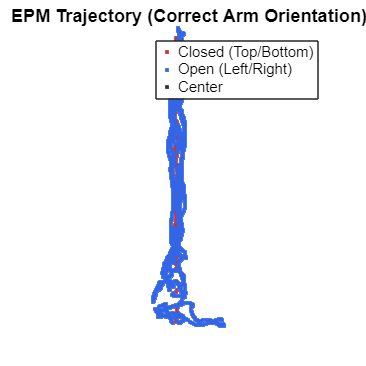

writetable(results,'EPM_Final_FixedOrientation.csv');

%% ================= PAPER-READY FIGURES =================
figure('Color','w','Position',[200 200 500 500]); hold on;
plot(Xb(zone_body==3),Yb(zone_body==3),'.','Color',[0.8 0.2 0.2]); % Closed
plot(Xb(zone_body==2),Yb(zone_body==2),'.','Color',[0.2 0.4 0.9]); % Open
plot(Xb(zone_body==1),Yb(zone_body==1),'.','Color',[0.2 0.2 0.2]); % Center
axis equal off;
legend({'Closed (Top/Bottom)','Open (Left/Right)','Center'});
title('EPM Trajectory (Correct Arm Orientation)');
print(gcf,'Fig_EPM_Trajectory_Fixed','-dpng','-r600');

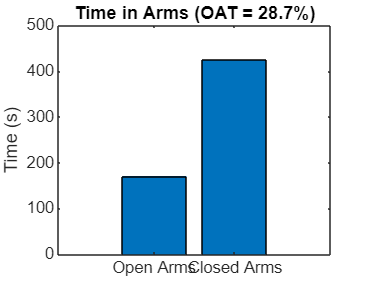


figure('Color','w','Position',[200 200 450 350]);
bar([time_open_s time_closed_s]);
set(gca,'XTickLabel',{'Open Arms','Closed Arms'});
ylabel('Time (s)');
title(sprintf('Time in Arms (OAT = %.1f%%)',OAT_percent));
print(gcf,'Fig_EPM_TimeInArms_Fixed','-dpng','-r600');

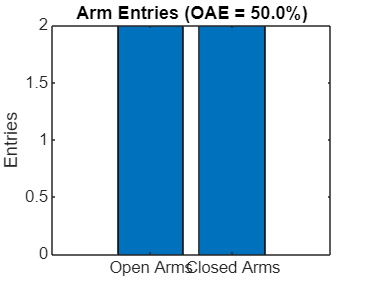


figure('Color','w','Position',[200 200 450 350]);
bar([entries_open entries_closed]);
set(gca,'XTickLabel',{'Open Arms','Closed Arms'});
ylabel('Entries');
title(sprintf('Arm Entries (OAE = %.1f%%)',OAE_percent));
print(gcf,'Fig_EPM_Entries_Fixed','-dpng','-r600');


%% ================= END =============================